# **Plot steel and reinforced concrete fiber sections**

**This function is primarily used to check section definitions.**

**This demo see also [opsvis](https://opsvis.readthedocs.io/en/latest/ex_plot_fiber_section.html)**

clc; clear;
opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

ops.wipe();
ops.model('basic', '-ndm', 2, '-ndf', 3);   % 2D frame

% For demonstration purposes only
ops.uniaxialMaterial('Elastic', 1, 1)
ops.uniaxialMaterial('Elastic', 2, 1)
ops.uniaxialMaterial('Elastic', 3, 1)
ops.uniaxialMaterial('Elastic', 4, 1)
ops.uniaxialMaterial('Elastic', 5, 1)

You need to set it to true to record fiber cross-section information.

opsMAT.pre.setSectionGeometryRecorder(true)

Then use the section-related commands normally:


%% 1. Rotated steel shape
% Section tag = 1

ops.section('Fiber', 1, '-GJ', 1.0e6);

ops.patch('quad', 1, 4, 1, ...
     0.032,  0.317, ...
    -0.311,  0.067, ...
    -0.266,  0.005, ...
     0.077,  0.254);

ops.patch('quad', 1, 1, 4, ...
    -0.075,  0.144, ...
    -0.114,  0.116, ...
     0.075, -0.144, ...
     0.114, -0.116);

ops.patch('quad', 1, 4, 1, ...
     0.266, -0.005, ...
    -0.077, -0.254, ...
    -0.032, -0.317, ...
     0.311, -0.067);

%% 2. RC section
% Section tag = 2

Bcol = 0.711;
Hcol = Bcol;

c = 0.076;   % cover

y1col = Hcol / 2.0;
z1col = Bcol / 2.0;

y2col = 0.5 * (Hcol - 2 * c) / 3.0;

nFibZ = 1;
nFib = 20;
nFibCover = 2;
nFibCore = 16;
As9 = 0.0006446;

ops.section('Fiber', 2, '-GJ', 1.0e6);

% core
ops.patch('rect', 2, nFibCore, nFibZ, ...
    c - y1col, c - z1col, ...
    y1col - c, z1col - c);

% cover patches
ops.patch('rect', 3, nFib, nFibZ, ...
    -y1col, -z1col, ...
     y1col,  c - z1col);

ops.patch('rect', 3, nFib, nFibZ, ...
    -y1col,  z1col - c, ...
     y1col,  z1col);

ops.patch('rect', 3, nFibCover, nFibZ, ...
    -y1col,  c - z1col, ...
     c - y1col, z1col - c);

ops.patch('rect', 3, nFibCover, nFibZ, ...
     y1col - c, c - z1col, ...
     y1col,     z1col - c);

% reinforcement layers
ops.layer('straight', 4, 4, As9, ...
     y1col - c, z1col - c, ...
     y1col - c, c - z1col);

ops.layer('straight', 4, 2, As9, ...
     y2col, z1col - c, ...
     y2col, c - z1col);

ops.layer('straight', 4, 2, As9, ...
    -y2col, z1col - c, ...
    -y2col, c - z1col);

ops.layer('straight', 4, 4, As9, ...
     c - y1col, z1col - c, ...
     c - y1col, c - z1col);

%% 3. Circular cross-section
% Section tag = 3

nc1 = 8; nr1 = 3;
nc2 = 8; nr2 = 2;

ri1 = 0.1;  re1 = 0.2;
ri2 = 0.2;  re2 = 0.25;

a_beg = 0.0; 
a_end = 360.0;

rbar3 = 0.225;
a_beg2 = 0.0; 
a_end2 = 360.0;

ops.section('Fiber', 3, '-GJ', 1.0e6);

ops.patch('circ', 2, nc1, nr1, ...
    0.0, 0.0, ri1, re1, a_beg, a_end);

ops.patch('circ', 3, nc2, nr2, ...
    0.0, 0.0, ri2, re2, a_beg, a_end);

ops.layer('circ', 4, 6, As9, ...
    0.0, 0.0, rbar3, a_beg2, a_end2);

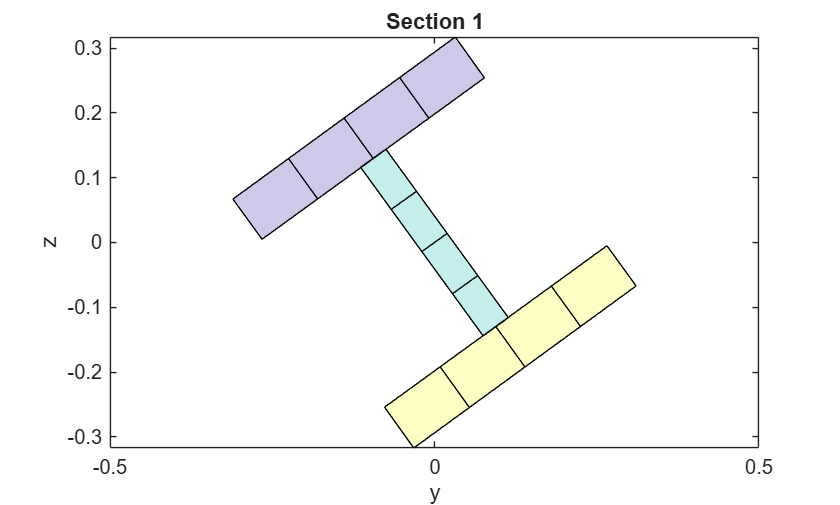

opsMAT.pre.plotSection(1);

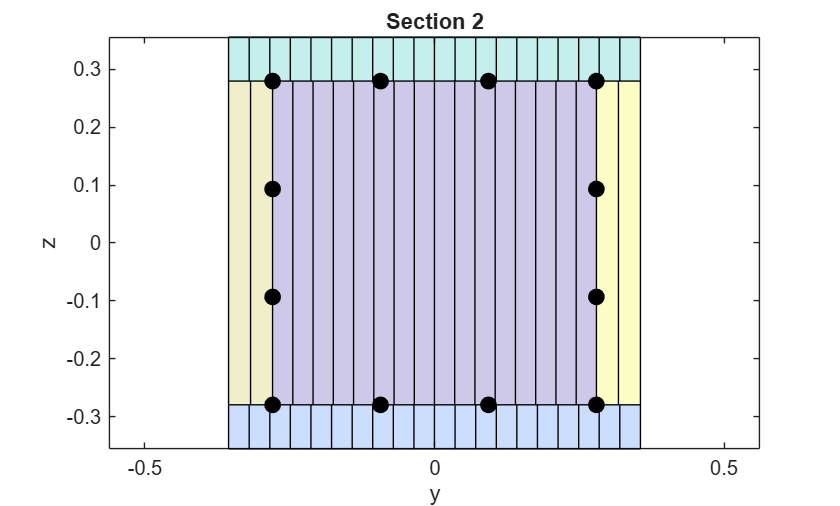

opsMAT.pre.plotSection(2);

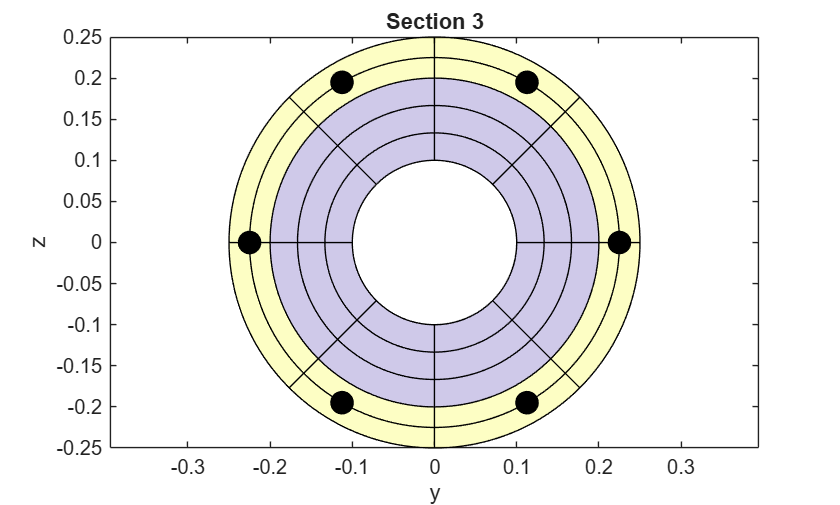

opsMAT.pre.plotSection(3);

opsMAT.pre.setSectionGeometryRecorder(false)  % off